This Live Script file will be presented to your end user in the Live Editor just as you see it here.  You can take advantage of all of the features of Live Script to present information and examples.

# Getting Started with <Gas mixture breakthrough curve simulation with IAST toolbox >

## 1. IAST calculation  

### 1.1 IAST introduction 

Ideal Solution Adsorption Theory, also known as Ideal Adsorbed Solution Theory (IAST), is a theoretical framework used to describe the behavior of multicomponent adsorption systems. It extends the concept of ideal solutions in liquid phase to adsorption processes. IAST is a powerful tool for understanding and predicting the behavior of multicomponent adsorption systems based on the properties of pure components. It plays a crucial role in optimizing adsorption processes in various industrial applications.

### 1.2 Function 

**[q_i]=IAST(isotherm_data_type,single_gas_isotherm,p_i,figure)**

**IAST calculation with isotherm model:**

**[q_i]=IAST(isotherm_data_type,single_gas_isotherm,p_i)**

**isotherm_data_type:** Type of single gas isotherm. Use  'Isotherm Model' for IAST calculation with isotherm model. 

**single_gas_isotherm: **A structure array including the information of single gas isotherm models for all the components in the gas mixture. 1$\times$Nc structs with 3 field: 'isotherm_type(1$\times$1 string ),'number_of_site'(single value), 'parameters'(1$\times$N matrix,N is number of parameters). For isotherm model doesn't involve 'number_of_site', it does't needs be specified. unit: pressure: Pa, uptake: mol/kg 

**p_i: ** Partial pressure of all components in the gas mixture. Nc$\times$1 matrix.  unit: Pa

**q_i:**  Component uptake in the gas mixture calculated with IAST. Nc$\times$1 matrix.  Please note that the order of **q_i ** corresponds to that of  **p_i**. unit: mol/kg

(Nc is number of components in the gas mixture) 

**IAST calculation with isotherm data points: **

**[q_i]=IAST(isotherm_data_type,single_gas_isotherm,p_i,figure)**

**isotherm_data_type:** Type of single gas isotherm. Use  'Isotherm Data Points'  for IAST calculation with isotherm data points.  

**single_gas_isotherm: **A structure array including the information of single gas isotherm data points for all the gas components in the gas mixture. 1$\times$Nc structs with 2 field:'adsorbate'(1$\times$1 string ),'isotherm_data'(N$\times$2 matrix). N is number of isotherm data points. unit: pressure: Pa, uptake: mol/kg. 

**p_i: **Partial pressure of all components in the gas mixture. Nc$\times$1 matrix. unit: Pa.

**figure: ** When user doesn't specify this variable, default setting is figure on. The figure can be turn off by specify this variable as 'figure off' . For IAST calculations using isotherm data points, there might be extrapolation of the single gas isotherms. The figure visualizes the extrapolation by plotting the gas phase partial pressure$p_i$, the adsorbed phase partial pressure $p_i^*$  obtained from the IAST calculation, and the isotherm data points on the same figure. Detail explanation can be found in the paper. 

**q_i:**   Component uptake in the gas mixture calculated with IAST. Nc$\times$1 matrix. Please note that the order of **q_i ** corresponds to that of  **p_i**. unit: mol/kg.

### 1.2 Warning and Error 

For numerical quadrature IAST calculations using isotherm data points, some warning and error messages may appear during the calculation. The detailed explanation and solutions for these issues are provided below.

$p_{i,\max }$**:** Maximum pressure in discrete single gas isotherm data points of component i in the gas mixture 

$p_i$**:** Parital pressure of component i in the gas mixture at gas phase 

$p_i^*$**:** Parital pressure of component i in the gas mixture at theoretical adsorbed liquid phase; 

In IAST numerical quadrature calculations, the uptake at $p_i$ is calculated using linear interpolation of discrete single isotherm data points. Different values of $p_i^*$ are attemped during iterative solving IAST  equations, and all these attempted values require uptake calculation using  linear interpolation of discrete single isotherm data points. Thus, it is crucial to ensure that  $p_{i,\max }$ exceed  $p_i$ and $p_i^*$. Failure to meet this condition can cause error and warning messages.

**case 1: **$p_i >p_{i,\max }$

Error massge:  Partial pressures of components in the gas mixture at the gas phase exceed their single gas isotherm data points' maximum pressure.

Solution: When this error message appears, the IAST calculation will stop, and the gas mixture uptake cannot be obtained. To fix this problem, measure equilibrium uptake at pressures higher than $p_i^*$ and update the single gas isotherm data points accordingly.

**case 2: **$p_i^* >p_{i,\max }$

Warning massge: Partial pressures of components in the gas mixture at the theoretical adsorbed liquid phase exceed their single gas isotherm data points' maximum pressure. Constant slope extrapolation is used to calculate the uptake.

Solution: The IAST calculation proceeds with a warning, and the gas mixture uptake can be obtained. The $p_i^*$ value will be printed in the command window. For better accuracy, equilibrium uptake at pressures higher than $p_i^*$ should be measured and the single gas isotherm data points should be updated. This step is optional but recommended for improved accuracy.

### 1.4 Example 

**IAST calculation with isotherm model: **

close all
clear 
single_gas_isotherm(1)=struct('isotherm_type',"Langmuir",'number_of_site',2,'parameters',[4.4,2.91*10^(-4),10,6.96*10^(-7)]);
single_gas_isotherm(2)=struct('isotherm_type',"Langmuir",'number_of_site',2,'parameters',[4.97,9.3*10^(-9),2.99,2.79*10^(-4)]);
p_i=[125000;125000];
[q_i]=IAST('Isotherm Model',single_gas_isotherm,p_i)

q_i =     4.2983
    0.5178


**IAST calculation with isotherm data points **

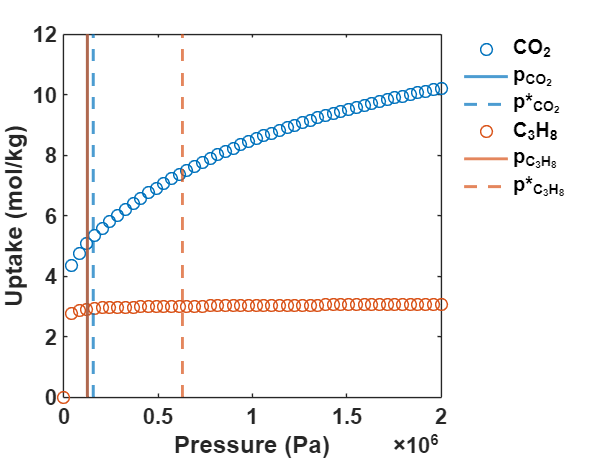

q_i =     3.6772
    0.9124


% obtain discrete single gas isotherm data points 
p_max=2000000;
ps=linspace(0,p_max,50)';
single_gas_isotherm_dp(1).isotherm_data(:,1)=ps;
single_gas_isotherm_dp(1).isotherm_data(:,2)=isotherm(single_gas_isotherm(1),ps,1);
single_gas_isotherm_dp(1).adsorbate="CO_2";
single_gas_isotherm_dp(2).isotherm_data(:,1)=ps;
single_gas_isotherm_dp(2).isotherm_data(:,2)=isotherm(single_gas_isotherm(2),ps,1);
single_gas_isotherm_dp(2).adsorbate="C_3H_8";
[q_i]=IAST('Isotherm Data Points',single_gas_isotherm_dp,p_i) 

% turn off the figure 
[q_i]=IAST('Isotherm Data Points',single_gas_isotherm_dp,p_i,'figure off') 

q_i =     3.6772
    0.9124


It can be seen that uptake calculation using only 50 isotherm data points deviates from that calculated using the isotherm model. This deviation occurs because, during IAST calculation, the uptake is calculated using linear interpolation of discrete isotherm data points. To address this problem, it is suggested to measure more isotherm data points for accurate calculation. An alternative approach is to find an equation that accurately captures the trend of the isotherm data points and use that equation to generate more data points. This measure reduces the error from linear interpolation but introduces the equation prediction error. The following code is an example of using a second-order polynomial fit equation to increase the number of isotherm data points from 50 to 450 and achieve more accurate IAST calculations.

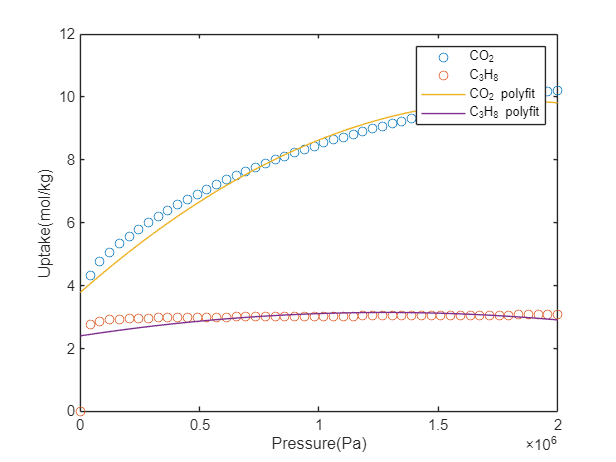

ps=linspace(single_gas_isotherm_dp(1).isotherm_data(1,1),single_gas_isotherm_dp(1).isotherm_data(end,1),450)';
p1=polyfit(single_gas_isotherm_dp(1).isotherm_data(:,1),single_gas_isotherm_dp(1).isotherm_data(:,2),2);
p2=polyfit(single_gas_isotherm_dp(2).isotherm_data(:,1),single_gas_isotherm_dp(2).isotherm_data(:,2),2);

new_single_gas_isotherm_dp(1).isotherm_data(:,1)=ps;
new_single_gas_isotherm_dp(1).isotherm_data(:,2)=polyval(p1,ps);
new_single_gas_isotherm_dp(1).adsorbate="CO_2";
new_single_gas_isotherm_dp(2).isotherm_data(:,1)=ps;
new_single_gas_isotherm_dp(2).isotherm_data(:,2)=polyval(p2,ps);
new_single_gas_isotherm_dp(2).adsorbate="C_3H_8";
figure
plot(single_gas_isotherm_dp(1).isotherm_data(:,1),single_gas_isotherm_dp(1).isotherm_data(:,2),'o');
hold on 
plot(single_gas_isotherm_dp(2).isotherm_data(:,1),single_gas_isotherm_dp(2).isotherm_data(:,2),'o');
hold on 
plot(new_single_gas_isotherm_dp(1).isotherm_data(:,1),new_single_gas_isotherm_dp(1).isotherm_data(:,2),'-');
hold on 
plot(new_single_gas_isotherm_dp(2).isotherm_data(:,1),new_single_gas_isotherm_dp(2).isotherm_data(:,2),'-');
legend('CO_2','C_3H_8','CO_2 polyfit','C_3H_8 polyfit')
xlabel('Pressure(Pa)')
ylabel('Uptake(mol/kg)')

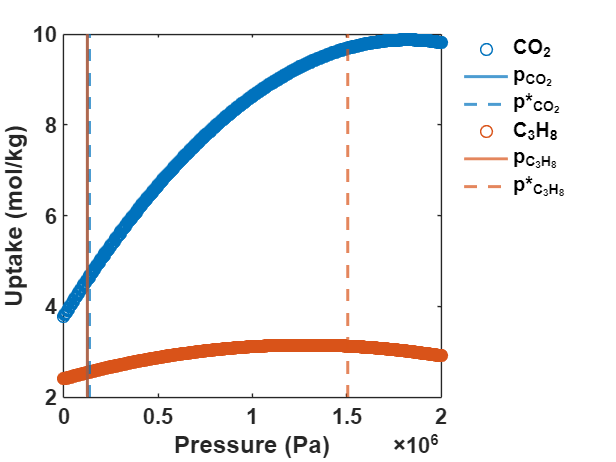

q_i =     4.1064
    0.3719


[q_i]=IAST('Isotherm Data Points',new_single_gas_isotherm_dp,p_i) 

## 2. Breakthrough curve simulation with IAST 

### 2.1 Breakthrough system introduction 

Breakthrough system is a lab-scale isothermal adsorption bed typically used for obtaining gas mixture equilibrium data. The breakthrough curve represents the partial pressure profile of the gas flowing out from the adsorption bed. Calculating adsorption kinetics from a breakthrough curve involves fitting the experimentally obtained breakthrough curve with one generated by an isothermal adsorption bed model. The LDF model describes the solid-phase mass balance in the breakthrough system model.

Obtaining the mass transfer coefficient from a gas mixture breakthrough experiment requires constructing a complete gas mixture isotherm, which is labor-intensive and rarely achieved in the lab. Therefore, this work focuses on obtaining mass transfer coefficients using single gas breakthrough curves. Two isothermal adsorption bed models are included in the package:

1. The pressure and velocity are constant throughout the adsorption bed, typically occurring in dilute feed flows with a carrier gas.

2. The pressure and velocity decrease along the adsorption bed, which is common for concentrated feed flows with effective adsorption. This also happens when the adsorbent particle size is very small, impeding the mobile phase and leading to significant pressure decay.

The assumptions and governing equations for the breakthrough system model are detailed in the paper.

### 2.2 Function

#### 2.2.1 **Constant pressure and velocity model: **

Before the feed of the inlet gas, the adsorption bed is at a total pressure of **P** with an adsorbate partial pressure 0 and the adsorbent inside the bed has an uptake of 0, When the inlet gas, with molar ratio **y_i **and total pressure **P, ** is fed to the adsorption bed. it maintains a constant velocity  **v** and a constant total pressure **P** throughout the whole bed.

**[output]=Breakthrough_simulation(adsorbent,isotherm_data_type,component_info,time,Nz,v,P,L,T,eps,rho,Dax,model_type,show_figure)**

**adsorbent: ** Adsorbent identity: 1$\times$1 string

**isotherm_data_type: **'Isotherm Model' or 'Isotherm Data Points'

**component_info: **

A structure array including the information of all gas components in the gas mixture: 1×Nc structs with 8 fields:

- 'adsorbate'(1×1 string),

- 'isotherm_type'(1×1 string),

- 'number_of_site'(single value, only required for multi-site isotherm models),

- 'parameters'(1×N matrix, N is number of model parameters. unit: pressure: Pa, uptake: mol/kg),

- 'y_if'(Feed molar ratio of adsorbate i. single value. unit: non),

- 'k_i'(Mass transfer coefficient of adsorbate i. single value. unit: 1/s),

- 'p_int_max'(Maximum partial pressure used for IAST interpolation. single value. suggested value: 1.5* P*y_if. unit: Pa),

- 'interpolation_size'(Grid size used for IAST interpolation. suggested value: 2000~5000. unit: Pa)

**time: **Total running time for breakthrough curve. unit: s

**Nz: **Number of discretization volume in the finite volume scheme. suggested value: 50. unit: non

**v: **Adsorption bed feed flow interstitial velocity. unit: m/s

**P: **Adsorption bed and it feed flow total pressure. unit: Pa

**L: **Adsorption bed length. unit: m

**T: **Adsorption bed and its feed flow temperature. unit: K

**eps: **Adsorption bed void fraction. unit: non

**rho: **Adsorbent density unit: kg/m^3

**Dax: **Axial dispersion coefficient.It is a coefficient that can characterize the degree of back-mixing and quantify the deviation from ideal plug flow behavior. unit: m^2/s

**model_type: **'Pv_constant'

**show_figure: **'figure on' or  'figure off'

#### **2.2.2 Pressure and velocity drop model: **

Before the feed of the inlet gas, the adsorption bed is at a total pressure of **P** with an adsorbate partial pressure 0 and the adsorbent inside the bed has an uptake of 0. When the inlet gas, with molar ratio **y_i **and total pressure **P, ** is fed to the adsorption bed. It has a velocity **v** regulated at bed entry and a total pressure **P **regulated at bed end. 

**[output]=Breakthrough_simulation(adsorbent,isotherm_data_type,component_info,time,Nz,v,P,L,T,eps,rho,Dax,model_type,show_figure,r_p,mu)**

**adsorbent: ** Adsorbent identity: 1$\times$1 string

**isotherm_data_type: **'Isotherm Model' or 'Isotherm Data Points'

**component_info: **

A structure array including the information of all gas components in the gas mixture: 1×Nc structs with 8 fields:

- 'adsorbate'(1×1 string),

- 'isotherm_type'(1×1 string),

- 'number_of_site'(single value, only required for multi-site isotherm models),

- 'parameters'(1×N matrix, N is number of model parameters. unit: pressure: Pa, uptake: mol/kg),

- 'y_if'(Feed molar ratio of adsorbate i. single value. unit: non),

- 'k_i'(Mass transfer coefficient of adsorbate i. single value. unit: 1/s),

- 'p_int_max'(Maximum partial pressure used for IAST interpolation. single value. suggested value: 1.5* P*y_if. unit: Pa),

- 'interpolation_size'(Grid size used for IAST interpolation. suggested value: 2000~5000. unit: Pa)

**time: **Total running time for breakthrough curve. unit: s

**Nz: **Number of discretization volume in the finite volume scheme. suggested value: 50. unit: non

**v: **Adsorption bed feed flow interstitial velocity. unit: m/s

**P: **Adsorption bed and it feed flow total pressure. unit: Pa

**L: **Adsorption bed length. unit: m

**T: **Adsorption bed and its feed flow temperature. unit: K

**eps: **Adsorption bed void fraction. unit: non

**rho: **Adsorbent density unit: kg/m^3

**Dax: **Axial dispersion coefficient.It is a coefficient that can characterize the degree of back-mixing and quantify the deviation from ideal plug flow behavior. unit: m^2/s

**model_type: **'Pv_constant'

**show_figure: **'figure on' or  'figure off'

**r_p: **Particle size of adsorbent. (only required for Pv_ drop model) unit:m 

**mu: **Viscosity of gas phase.(only required for Pv_ drop model) Unit: kg/(ms)

**When tuning the adsorption bed parameters for breakthrough curve simulation, both the gas mixture isotherm grid  and interpolation function  are generated repeatly,which leads to a high computation cost. To solve this problem, the following function enables seperation of  gas mixture isotherm interpolation function  generation and breakthrough curve simulation.**

#### 2.2.3 Gas mixture isotherm calculation with IAST and spline interpolation function generation 

**[new_component_info]=IAST_interpolation(isotherm_data_type,component_info)**

**isotherm_data_type: **'Isotherm Model' or 'Isotherm Data Points'

**component_info: **

A structure array including the information of all gas components in the gas mixture: 1×Nc structs with 8 fields:

- 'adsorbate'(1×1 string),

- 'isotherm_type'(1×1 string),

- 'number_of_site'(single value, only required for multi-site isotherm models),

- 'parameters'(1×N matrix, N is number of model parameters. unit: pressure: Pa, uptake: mol/kg),

- 'y_if'(Feed molar ratio of adsorbate i. single value. unit: non),

- 'k_i'(Mass transfer coefficient of adsorbate i. single value. unit: 1/s),

- 'p_int_max'(Maximum partial pressure used for IAST interpolation. single value. suggested value: 1.5* P*y_if. unit: Pa),

- 'interpolation_size'(Grid size used for IAST interpolation. suggested value: 2000~5000. unit: Pa)

#### 2.2.4 **Constant pressure and velocity model using pregenerated interpolation function **

**[output]=IAST_Breakthrough(adsorbent,isotherm_data_type,component_info,time,Nz,v,P,L,T,eps,rho,Dax,model_type,show_figure)**

**isotherm_data_type: **'Isotherm Model' or 'Isotherm Data Points'

**component_info: **

A structure array including the information of all gas components in the gas mixture: 1×Nc structs with 8 fields:

- 'adsorbate'(1×1 string),

- 'isotherm_type'(1×1 string),

- 'number_of_site'(single value, only required for multi-site isotherm models),

- 'parameters'(1×N matrix, N is number of model parameters. unit: pressure: Pa, uptake: mol/kg),

- 'y_if'(Feed molar ratio of adsorbate i. single value. unit: non),

- 'k_i'(Mass transfer coefficient of adsorbate i. single value. unit: 1/s),

- 'p_int_max'(Maximum partial pressure used for IAST interpolation. single value. suggested value: 1.5* P*y_if. unit: Pa),

- 'interpolation_size'(Grid size used for IAST interpolation. suggested value: 2000~5000. unit: Pa)

**time: **Total running time for breakthrough curve. unit: s

**Nz: **Number of discretization volume in the finite volume scheme. suggested value: 50. unit: non

**v: **Adsorption bed feed flow interstitial velocity. unit: m/s

**P: **Adsorption bed and it feed flow total pressure. unit: Pa

**L: **Adsorption bed length. unit: m

**T: **Adsorption bed and its feed flow temperature. unit: K

**eps: **Adsorption bed void fraction. unit: non

**rho: **Adsorbent density unit: kg/m^3

**Dax: **Axial dispersion coefficient.It is a coefficient that can characterize the degree of back-mixing and quantify the deviation from ideal plug flow behavior. unit: m^2/s

**model_type: **'Pv_constant'

**show_figure: **'figure on' or  'figure off'

**2.2.5 Pressure and velocity drop model using pregenerated interpolation function **

**[output]=IAST_Breakthrough(adsorbent,isotherm_data_type,component_info,time,Nz,v,P,L,T,eps,rho,Dax,model_type,show_figure,r_p,mu)**

**isotherm_data_type: **'Isotherm Model' or 'Isotherm Data Points'

**component_info: **

A structure array including the information of all gas components in the gas mixture: 1×Nc structs with 8 fields:

- 'adsorbate'(1×1 string),

- 'isotherm_type'(1×1 string),

- 'number_of_site'(single value, only required for multi-site isotherm models),

- 'parameters'(1×N matrix, N is number of model parameters. unit: pressure: Pa, uptake: mol/kg),

- 'y_if'(Feed molar ratio of adsorbate i. single value. unit: non),

- 'k_i'(Mass transfer coefficient of adsorbate i. single value. unit: 1/s),

- 'p_int_max'(Maximum partial pressure used for IAST interpolation. single value. suggested value: 1.5* P*y_if. unit: Pa),

- 'interpolation_size'(Grid size used for IAST interpolation. suggested value: 2000~5000. unit: Pa)

**time: **Total running time for breakthrough curve. unit: s

**Nz: **Number of discretization volume in the finite volume scheme. suggested value: 50. unit: non

**v: **Adsorption bed feed flow interstitial velocity. unit: m/s

**P: **Adsorption bed and it feed flow total pressure. unit: Pa

**L: **Adsorption bed length. unit: m

**T: **Adsorption bed and its feed flow temperature. unit: K

**eps: **Adsorption bed void fraction. unit: non

**rho: **Adsorbent density unit: kg/m^3

**Dax: **Axial dispersion coefficient.It is a coefficient that can characterize the degree of back-mixing and quantify the deviation from ideal plug flow behavior. unit: m^2/s

**model_type: **'Pv_constant'

**show_figure: **'figure on' or  'figure off'

**r_p: **Particle size of adsorbent. (only required for Pv_ drop model) unit:m 

**mu: **Viscosity of gas phase.(only required for Pv_ drop model) Unit: kg/(ms)

### 2.4 Example 

#### 2.4.1 Single gas breakthrough curve simulation without IAST 

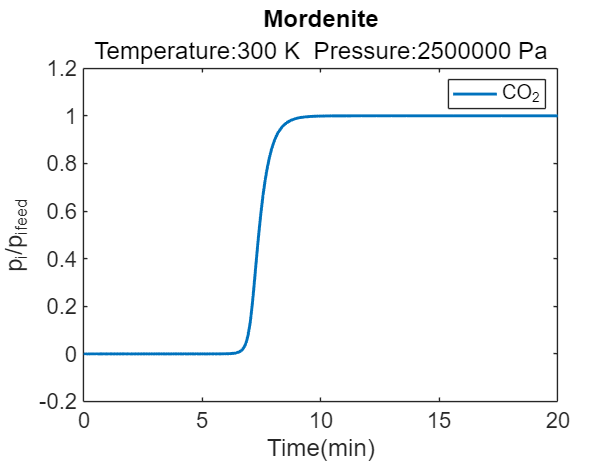

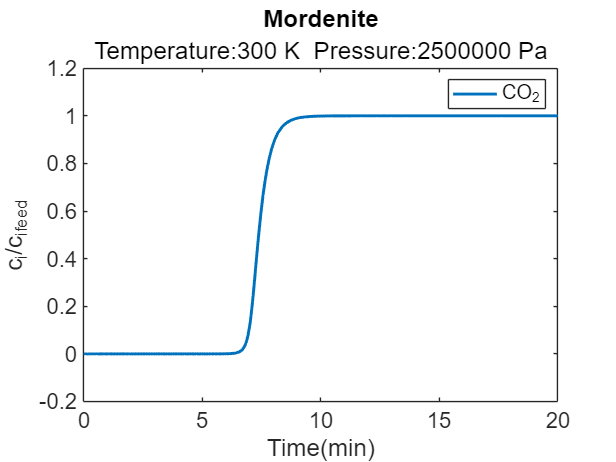

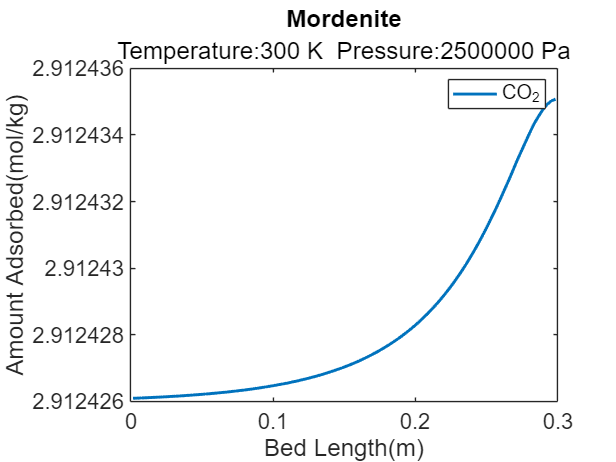

clear
close all
adsorbent="Mordenite"; 
adsorbate=["CO_2"];
t=1200; % time (s) (how long you want the experiment run)
Nc=1;%number of component
Nz=100;%number of grid points 
y_i=[0.05];% feed molar ratio
% Interstitial velocity (m/s)
% for noPD, Interstitial velocity is constant for the bed 
% for withPD, this is the Interstitial velocity specified at the beginning of the bed.
v =0.1;
% pressure (Pa) 
% for noPD, pressure is constant for the whole bed 
% for withPD, this is the pressure regulated at the end of the bed.
P=2.5*10^6;
L=0.3;% bed length (m)
T=300;% bed temperature (K)
eps=0.4;% bed void space
k_i=[0.06];% mass transfer coefficient (s^-1)
Dax=0.01;% axial diffusion coefficient (m^2/s)
rho=1693.89;% adsorbent density (kg/m^3)
r_p=0.0005;% adsorbent particle radius(m)
mu=1.85*10^(-5);% air viscosity at 25c kg/(ms) 


% isotherm model
% unit: q(mol/kg),p(Pa)

component_info=struct('adsorbate',"CO_2",'isotherm_type',"Langmuir",'number_of_site',2,'parameters',[4.97,9.3*10^(-9),2.99,2.79*10^(-4)],...
    'y_if',0.05,'k_i',0.06);

% convert isotherm model to data 
n_points=100;
p1=linspace(0,200000,n_points)';
new_component_info=rmfield(component_info,{'isotherm_type','number_of_site','parameters'});
for i =1 : Nc
    new_component_info(i).isotherm_data(:,1)=p1;
    new_component_info(i).isotherm_data(:,2)=isotherm(component_info(i),p1,1);

end 

% %calculate feed concentration and partial pressure


[output]=Breakthrough_simulation(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');

% [output]=Breakthrough_simulation(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_drop','figure on',r_p,mu);
% [output]=Breakthrough_simulation(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');
% [output]=Breakthrough_simulation(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on',r_p,mu);


#### 2.4.2 Binary gas breakthrough curve simulation with IAST 

The IAST calculated mixture isotherm grid size is 126  251
Finished points:10000 Total points:31626
Finished points:20000 Total points:31626
Finished points:30000 Total points:31626
IAST calculation is done


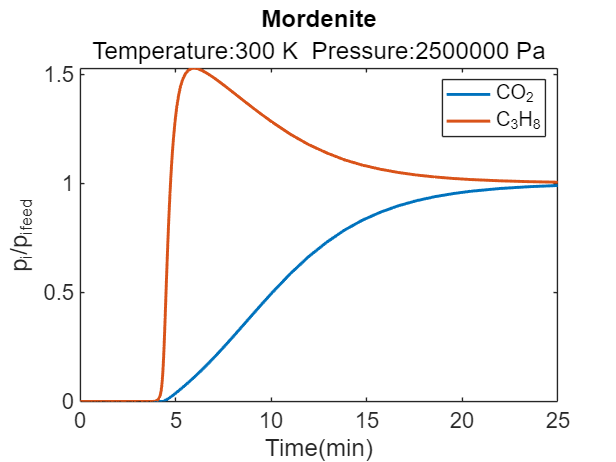

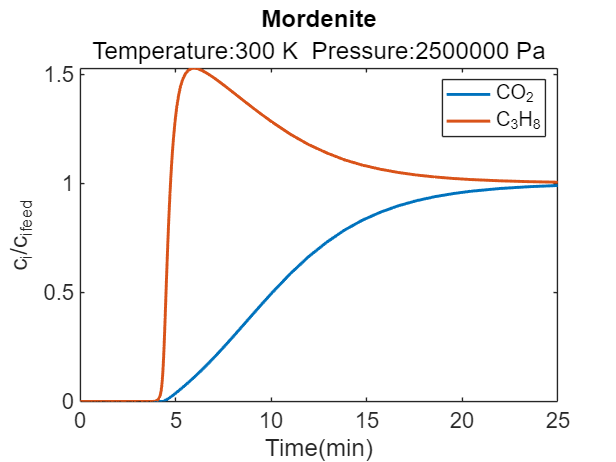

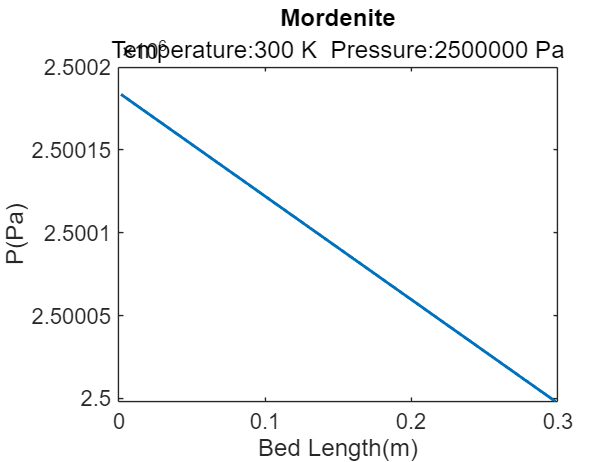

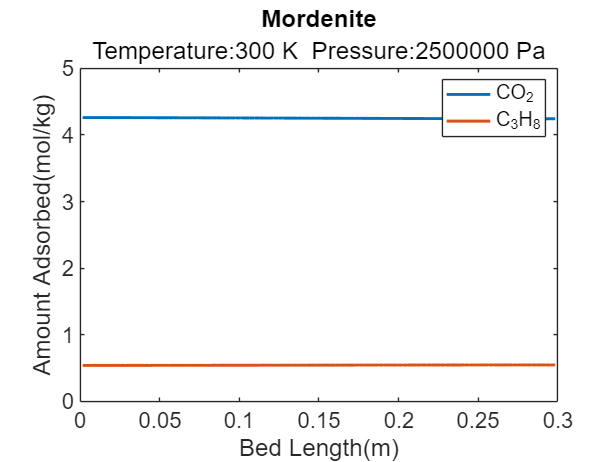

close all 
clear 
adsorbent="Mordenite"; 
t=1500; % time (s) (how long you want the experiment run)
Nz=100;%number of grid points 

% Interstitial velocity (m/s)
% for noPD, Interstitial velocity is constant for the bed 
% for withPD, this is the Interstitial velocity specified at the beginning of the bed.
v =0.1;
% pressure (Pa) 
% for noPD, pressure is constant for the whole bed 
% for withPD, this is the pressure regulated at the end of the bed.
P=2.5*10^6;
L=0.3;% bed length (m)
T=300;% bed temperature (K)
eps=0.4;% bed void space
Dax=0.01;% axial diffusion coefficient (m^2/s)
rho=1693.89;% adsorbent density (kg/m^3)
r_p=0.0005;% adsorbent particle radius(m)
mu=1.85*10^(-5);% air viscosity at 25c kg/(ms) 



% isotherm model
% unit: q(mol/kg),p(Pa)

component1=struct('adsorbate',"CO_2",'isotherm_type',"Langmuir",'number_of_site',2,'parameters',[4.4,2.91*10^(-4),10,6.96*10^(-7)],...
    'y_if',0.05,'k_i',0.06,'p_int_max',1*0.05*P,'interpolation_size',1000);
component2=struct('adsorbate',"C_3H_8",'isotherm_type',"Langmuir",'number_of_site',2,'parameters',[4.97,9.3*10^(-9),2.99,2.79*10^(-4)],...
    'y_if',0.05,'k_i',0.06,'p_int_max',2*0.05*P,'interpolation_size',1000);
component_info=[component1;component2];


% convert isotherm model to data 
n_points=1000;
p1=linspace(0,2000000,n_points)';
new_component_info=rmfield(component_info,{'isotherm_type','number_of_site','parameters'});
for i =1 : 2
    new_component_info(i).isotherm_data(:,1)=p1;
    new_component_info(i).isotherm_data(:,2)=isotherm(component_info(i),p1,1);

end 


%% one step breakthrough simulation 

% [output]=Breakthrough_simulation(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');
% [output]=Breakthrough_simulation(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_drop','figure on',r_p,mu);
% [output]=Breakthrough_simulation(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');
[output]=Breakthrough_simulation(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_drop','figure on',r_p,mu);

#### 2.4.3 Binary gas breakthrough curve simulation with IAST using two functions

% 1st step obtain the interpolation function Fs for IAST calculated mixture isotherm matrix.
% Isotherm Model
[component_info]=IAST_interpolation('Isotherm Model',component_info);

The IAST calculated mixture isotherm grid size is 126  251
Finished points:10000 Total points:31626
Finished points:20000 Total points:31626
Finished points:30000 Total points:31626
IAST calculation is done


%Isotherm Data Points
[new_component_info]=IAST_interpolation('Isotherm Data Points',new_component_info);

The IAST calculated mixture isotherm grid size is 126  251
Finished points:10000 Total points:31626
Finished points:20000 Total points:31626
Finished points:30000 Total points:31626
IAST calculation is done


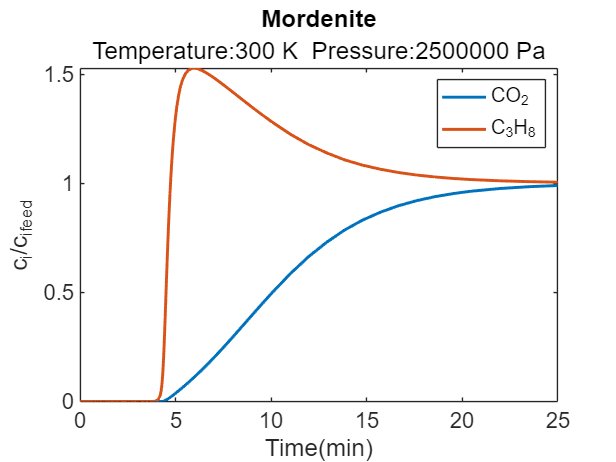


%Isotherm Model


%% 2nd step breakthrough simulation 
% [output]=IAST_Breakthrough(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');
% [output]=IAST_Breakthrough(adsorbent,'Isotherm Model',component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_drop','figure on',r_p,mu);
% [output]=IAST_Breakthrough(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_constant','figure on');
[output]=IAST_Breakthrough(adsorbent,'Isotherm Data Points',new_component_info,t,Nz,v,P,L,T,eps,rho,Dax,'Pv_drop','figure on',r_p,mu);